Q = [1,0,0,0;...
0,0,0,0;...
0,0,0,0;...
0,0,0,0];
R = 1.0;

rg_val = 0.0254;
L_val = 0.4255;
g_val = 9.81;
K_val = 1.5;
tau_val = 0.025;

syms x1 x2 x3 x4 u g rg L K tau v real
f = [ 
    x2;
    (5*g*rg/(7*L)) * sin(x3) - (5/7) * ((L/2) - x1) * ((rg/L)^2) * x4^2 * cos(x3)^2;
    x4;
    -x4/tau
];
g_vec = [0; 0; 0; K/tau];
f+g_vec*u

$$ans = \left(\begin{array}{c} x_{2}\\ \frac{5\,g\,\mathrm{rg}\,\sin\left(x_{3}\right)}{7\,L}-\frac{{\mathrm{rg}}^{2}\,{x_{4}}^{2}\,{\cos\left(x_{3}\right)}^{2}\,\left(\frac{5\,L}{14}-\frac{5\,x_{1}}{7}\right)}{L^{2}}\\ x_{4}\\ \frac{K\,u}{\tau }-\frac{x_{4}}{\tau } \end{array}\right)$$



h = x1; 
Lfh = simplify(jacobian(h, [x1; x2; x3; x4]) * (f+g_vec*u));
Lf2h = simplify(jacobian(Lfh, [x1; x2; x3; x4]) * (f+g_vec*u));
Lf3h = simplify(jacobian(Lf2h, [x1; x2; x3; x4]) * (f+g_vec*u));
Lf3h_discard = simplify(expand(Lf3h) - (-(5*K*rg^2*u*x4*cos(x3)^2)/(7*L*tau) + (10*K*rg^2*u*x1*x4*cos(x3)^2)/(7*L^2*tau)));
Lf4h = jacobian(Lf3h_discard, [x1; x2; x3; x4]) * (f+g_vec*u);
u_sol = simplify(solve(Lf4h == v, u));

symbols = {g, rg, L, K, tau};
consts = {g_val, rg_val, L_val, K_val, tau_val};
u_sol = subs(u_sol, symbols, consts);
h = subs(h, symbols, consts);
Lfh = subs(Lfh, symbols, consts);
Lf2h = subs(Lf2h, symbols, consts);
Lf3h_discard = subs(Lf3h_discard, symbols, consts);
            
u_fn = matlabFunction(u_sol, 'Vars', [x1, x2, x3, x4, v]);
h_fn = matlabFunction(h, 'Vars', [x1, x2, x3, x4]);
Lfh_fn = matlabFunction(Lfh, 'Vars', [x1, x2, x3, x4]);
Lf2h_fn = matlabFunction(Lf2h, 'Vars', [x1, x2, x3, x4]);
Lf3h_fn = matlabFunction(Lf3h_discard, 'Vars', [x1, x2, x3, x4]);

A = zeros(4,4);  % Initialize a 4x4 zero matrix
A(1:3,2:4) = eye(3);  % Set the top-right 3x3 block to identity
B = [0; 0; 0; 1];
[K,S,P] = lqr(A,B,Q,R);

disp(K);

    1.0000    2.6131    3.4142    2.6131




syms x1 x2 x3 x4 u g rg L K tau v real

% Nonlinear function φ(y, z, u)
phi = @(x1, x3, x4) [ 
    0;
    (5*g*rg/(7*L)) * sin(x3) - (5/7) * ((L/2) - x1) * ((rg/L)^2) * x4^2 * cos(x3)^2
];

% Linear parts
A = [0 1; 0 0];         % For x = [x1; x2]
C = [1 0];              % y1 = Cx

F = [0 1; 0 -1/tau];    % For z = [x3; x4]
G = [0; K/tau];         % Input to z
H = [1 0];              % y2 = Hz

syms x1 x2 x3 x4 u 
system = [
    A * [x1; x2] + phi(x1, x3, x4);
    F * [x3; x4] + G * u;
]

$$system = \left(\begin{array}{c} x_{2}\\ \frac{5\,g\,\mathrm{rg}\,\sin\left(x_{3}\right)}{7\,L}-\frac{{\mathrm{rg}}^{2}\,{x_{4}}^{2}\,{\cos\left(x_{3}\right)}^{2}\,\left(\frac{5\,L}{14}-\frac{5\,x_{1}}{7}\right)}{L^{2}}\\ x_{4}\\ \frac{K\,u}{\tau }-\frac{x_{4}}{\tau } \end{array}\right)$$


phi = @(x1, x3, x4) [ 
    0;
    (5*g_val*rg_val/(7*L_val)) * sin(x3) - (5/7) * ((L_val/2) - x1) * ((rg_val/L_val)^2) * x4^2 * cos(x3)^2
];

A = [0.0 1; 0 0];         % For x = [x1; x2]
C = [1.0 0];              % y1 = Cx

F = [0 1; 0 -1/tau_val];    % For z = [x3; x4]
G = [0; K_val/tau_val];         % Input to z
H = [1.0 0];              % y2 = Hz

% Observer design weights (tune Q_o and R_o as needed)
Qx = eye(2);   % Penalize estimation error in x1 and x2
Rx = 0.1;        % Penalize measurement usage

Qz = eye(2);   % Penalize estimation error in z1 and z2
Rz = 0.1;

% LQR for observers (dual system)
Kx = lqr(A', C', Qx, Rx)';
Kz = lqr(F', H', Qz, Rz)';
disp(Kx);

    4.0404
    3.1623



disp(Kz);

    3.1632
    0.0029




% xhat_dot = A*xh + phi(y1, y2, zh(2)) + Kx*(y1-C*xh);
% zhat_dot = F*zhat + G*u + Kz*(y2 - H*zh);



% Time-varying input
function u = controller(t, s)
    K = [10.0000   14.6947   10.7967    4.6469];
    z_fn = @(x1,x2,x3,x4,x1r,x2r,x3r,x4r) [
        x1-x1r;
        x2-x2r;
        (124587*sin(x3))/297850 + (64516*x4^2*cos(x3)^2*((5*x1)/7 - 851/5600))/18105025 - x3r;
        (20320000*x4*cos(x3)*((108077*x4^2*sin(x3))/400000000 + (108077*x4*cos(x3))/10000000 - (127*x1*x4*cos(x3))/2500 + (127*x2*x4*cos(x3))/200000 - (127*x1*x4^2*sin(x3))/100000 + 834831/8000000))/5069407 - x4r;
    ];
    u_fn = @(x1,x2,x3,x4,v) (4000000000*((25698887331649*v)/12800000000000000 + (537476460632559*x4^2*sin(x3))/640000000000000000 - (1710053628273*x4^2*(sin(x3) - sin(x3)^3))/800000000000000000 + (69581560143053*x4^2*cos(x3)^2)/10000000000000000 - (69581560143053*x4^4*cos(x3)^2)/16000000000000000000 + (221383089491*x4^4*cos(x3)^4)/80000000000000000000 + (69581560143053*x4^3*sin(2*x3))/320000000000000000 - (81764465503*x1*x4^4)/8000000000000000 + (537476460632559*x4*cos(x3))/16000000000000000 + (69581560143053*x4^4)/32000000000000000000 - (81764465503*x1*x4^2*cos(x3)^2)/2500000000000 + (81764465503*x2*x4^2*cos(x3)^2)/100000000000000 + (81764465503*x1*x4^4*cos(x3)^2)/4000000000000000 - (260144641*x1*x4^4*cos(x3)^4)/20000000000000000 - (81764465503*x1*x4^3*sin(2*x3))/80000000000000 + (81764465503*x2*x4^3*sin(2*x3))/8000000000000000))/(1931444067*cos(x3)*((324231*x4^2*sin(x3))/400000000 + (108077*x4*cos(x3))/5000000 - (127*x1*x4*cos(x3))/1250 + (127*x2*x4*cos(x3))/100000 - (381*x1*x4^2*sin(x3))/100000 + 834831/8000000));
    fbl = @(x,xr) u_fn(x(1), x(2), x(3), x(4), - K * z_fn(x(1),x(2),x(3),x(4),xr(1),xr(2),xr(3),xr(4)));

    x = s(1:4);
    [p_ball_ref, v_ball_ref, a_ball_ref] = get_ref_traj(t);
    xr = [p_ball_ref; v_ball_ref; a_ball_ref; 0];

    u = fbl(x,xr);
end

% ODE function
odefun = @(t, s) [
    % Real system
    A * s(1:2) + phi(s(1), s(3), s(4));
    F * s(3:4) + G * controller(t, s);

    % Observer system
    A * s(5:6) + phi(s(1), s(3), s(8)) + Kx * (s(1) - C * s(5:6));
    F * s(7:8) + G * controller(t, s) + Kz * (s(3) - H * s(7:8))
];

% Initial conditions: [x1; x2; x3; x4; x1hat; x2hat; x3hat; x4hat]
s0 = [-.19; 0.0; 0.; 0.0; 0.0; 0.0; 0.0; 0.0];

% Time span
tspan = [0.0 100.0]

tspan =      0   100


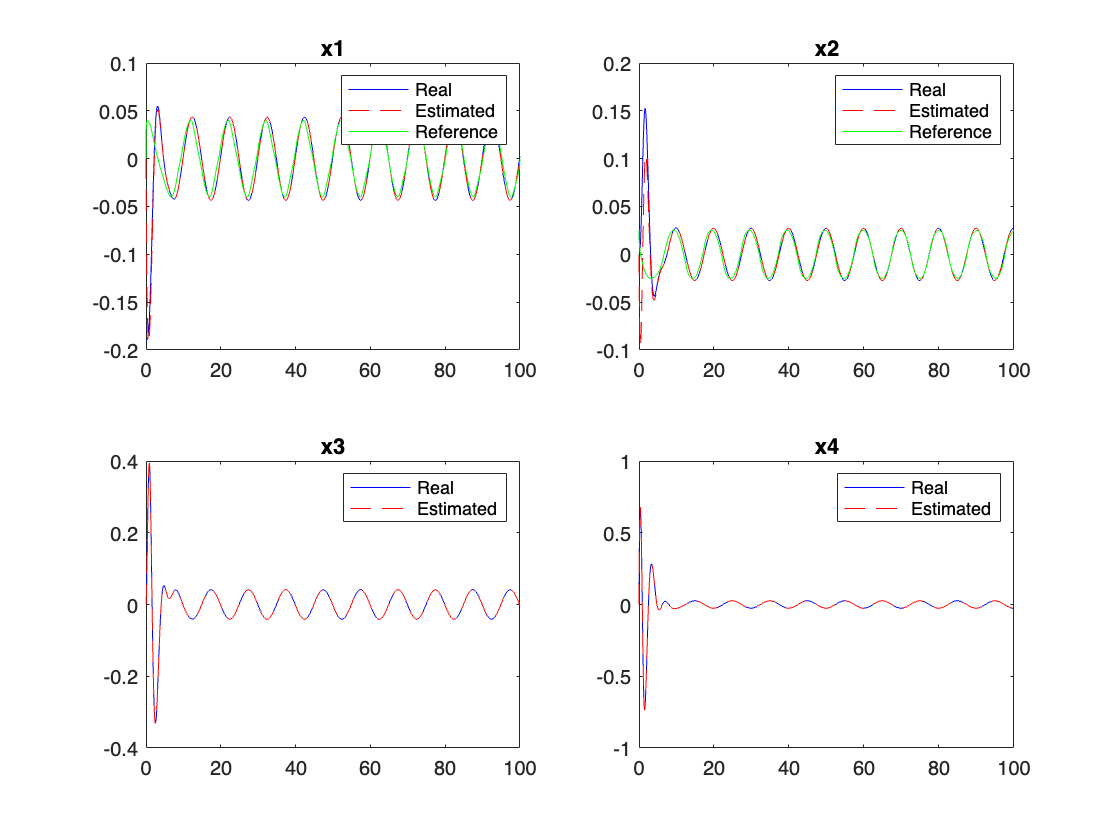


% Solve
[t, S] = ode45(odefun, tspan, s0);

% Extract states
x = S(:,1:2);      % real beam
z = S(:,3:4);      % real ball
xh = S(:,5:6);     % estimated beam
zh = S(:,7:8);     % estimated ball

[p_ball_ref, v_ball_ref, a_ball_ref] = get_ref_traj(linspace(tspan(1), tspan(2), length(x)));

% Plotting
figure;
subplot(2,2,1); plot(t, x(:,1), 'b', t, xh(:,1), 'r--', t, p_ball_ref', 'g');
title('x1'); legend('Real','Estimated', 'Reference');

subplot(2,2,2); plot(t, x(:,2), 'b', t, xh(:,2), 'r--', t, v_ball_ref', 'g');
title('x2'); legend('Real','Estimated', 'Reference');

subplot(2,2,3); plot(t, z(:,1), 'b', t, zh(:,1), 'r--');
title('x3'); legend('Real','Estimated');

subplot(2,2,4); plot(t, z(:,2), 'b', t, zh(:,2), 'r--');
title('x4'); legend('Real','Estimated');